# Proximity Analysis

This code, imports the 2 color images. They need to be in "tiff" format, maximum 16 bit, and the name of the file should not contain points or weird simbols (/,\,*, etc). The different channels need to be splitted beforehand, and it is indicated in the file name by the end as "-1" or "-2". 

A mask of the vesicle structures is performed with an intensity threshold, selected for each channel. This mask is used for the identification of the structure boundaries. The centroid position is calculated, and used for the nearest neightbour calculation. 

## Data organization

In this section, one selects the full list of tiff files for a certain condition. All the image paths are ordered by sets (rows). In the first column one finds all channel 1 images, and in the second column the second channel images. 

[filename,path] = uigetfile('*.*','All Files (*.*)',...
                'Select files','MultiSelect','on');
path = string(path) + string(filename); %final string with the path
n_img = length(filename);
%we classify each image by the last characters (-1 or -2)
for i = 1:n_img
    name = split(filename{i},'.');
    name = name{1};
    name = split(name,'-');
    name = name{end-1}; %cell of character vectors
    name = split(name,'_');
    g = name{end};
    groups{i} = g;
end
groups = unique(groups); % sets of images of the same field of view
files = cell(length(groups),2);
for i = 1:n_img
    name = split(filename{i},'.');
    name = name{1};
    name = split(name,'-');
    clas = string(name{end}); %cell of strings
    im = string(name{end-1});
    im = split(im,'_');
    im = im{end};
    c = find(strcmp(groups, im));
    if clas(1,1) == "2"
        files{c,2} = path{i};
    elseif clas(1,1) == "1"
        files{c,1} = path{i};
    end
end
clearvars c clas filename i name path g index im

## Selection of the threshold

Select different sets of images, in order to find an appropriate intensity threshold for the selection of the vesicles. The same threshold will be used for all image fields, so make sure that it more or less fits all of the sets. 

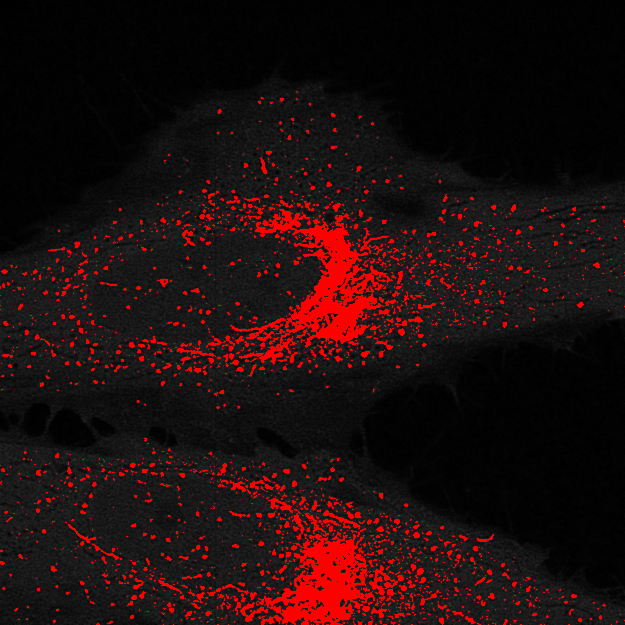

%% Select one image
i = 4;
ch = 1;
% Import image
warning('off','all')
ImageDataStore = datastore(files{i,ch},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    image = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    image = zeros(image_h,image_w,'uint16');
else
    image = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,ch},'r'); % read tiff file from pathway
image  = tstack.read(); % creates empty matrix with the image properties
image_j = imreducehaze(image);
image_j = imgaussfilt(image_j,1.5); %gaussian filter applied
image_j = uint8(image_j/256);
%imhist(image_j)

%% Select Threshold
th = [mean(image_j,'all') + std(double(image_j),0,'all'),256];
%% Binary image
binary = image_j >= th(1,1) & image_j <= th(1,2); 
%% Colored image
redChannel = image_j;
greenChannel = image_j;
blueChannel = image_j;
redChannel(binary) = 256;
greenChannel(binary) = 0;
blueChannel(binary) = 0;
% Concatenate r, g, and b channels to form RGB image
rgbImage = cat(3, redChannel, greenChannel, blueChannel);
%% Represent
imshow(rgbImage(:,:,:))

clearvars binary BitDepth blueChannel ch data greenChannel i image_h image_j image_w ImageDataStore th redChannel rgbImage tstack

## Make Mask

One you have decided a threshold intensity for each of the channels, select both values and execute this section. It is better to explore in the previous section and select one different intensity threshold for each of the channels. Select the minimum and maximum sizes of the structures that you want to segment as well. 

min_s = 10; %minimum size of the structures in px
max_s = 300; %maximum size 
n_sets = length(files);
boundaries = cell(2,n_sets);
centroids = cell(2,n_sets);
areas = cell(2,n_sets);
for i = 1:n_sets %For each set of 3 images
    %% Import the TGN image of each set
    warning('off','all')
    for j = 1:2 %for each channel
        ImageDataStore = datastore(files{i,j},'ReadFcn',@imfinfo);
        data = readall(ImageDataStore);
        image_w = data{1,1}.Width;
        image_h = data{1,1}.Height;
        BitDepth = data{1,1}.BitDepth;
        if BitDepth == 8
            image = zeros(image_h,image_w,'uint8');
        elseif BitDepth == 16
            image = zeros(image_h,image_w,'uint16');
        else
            image = zeros(image_h,image_w,'double');
        end
        tstack  = Tiff(files{i,j},'r'); % read tiff file from pathway
        image  = tstack.read(); % creates empty matrix with the image properties
        image_j = imreducehaze(image);
        image_j = imgaussfilt(image_j,1.5); %gaussian filter applied
        image_j = uint8(image_j/256);
        %% Find threshold
        th = [mean(image_j,'all') + std(double(image_j),0,'all'),256];
        % Get binary with threshold
        binary = image_j >= th(1,1) & image_j <= th(1,2); 
        %% vesicles extraction
        [h,w,f] = size(image);
        image(binary == 0) = 0;
        boundaries_j = cell(0,0);
        areas_j = [];
        centroids_j = [];
        boundary = bwboundaries(binary(:,:),'noholes');
        if ~isempty(boundary) == 1
            for k = 1:length(boundary)
                area = polyarea(boundary{k,1}(:,1),boundary{k,1}(:,2));
                polyin = polyshape(boundary{k,1}(:,:));
                [x,y] = centroid(polyin);
                center = [x,y];
                if area > min_s & area < max_s %structures should be within this size limits (area in px)
                    boundaries_j = [boundaries_j;boundary{k,1}];
                    areas_j = [areas_j;area];
                    centroids_j = [centroids_j;center];
                end
            end
        end
        boundaries{j,i} = boundaries_j;
        areas{j,i} = areas_j;
        centroids{j,i} = centroids_j;
    end
end
clearvars -except files n_img n_sets centroids areas boundaries

### Visualization of the segmentation

Select one set (i) and one channel (ch) for the visualization of the segmented structures. 

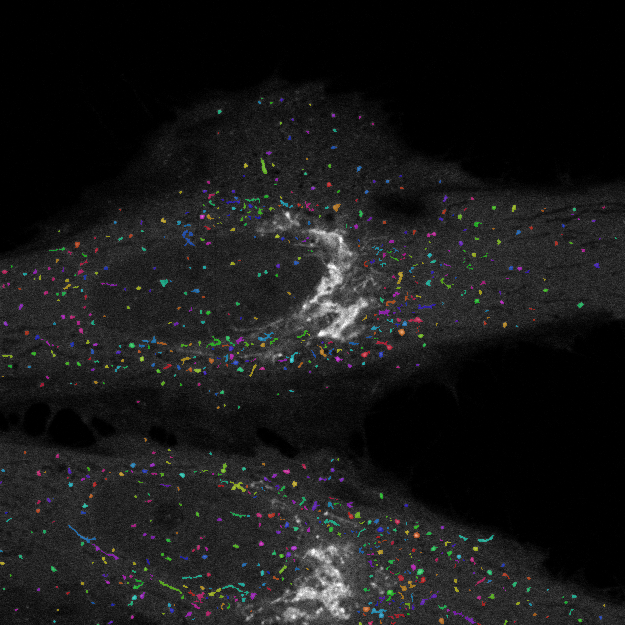

i = 4; %image
ch = 1; %channel (1 or 2)
%% Import the TGN image of each set
warning('off','all')
ImageDataStore = datastore(files{i,ch},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    image = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    image = zeros(image_h,image_w,'uint16');
else
    image = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,ch},'r'); % read tiff file from pathway
image(:,:)  = tstack.read(); % creates empty matrix with the image properties
warning('on','all')
image = uint8(image/256);
%% label matrix for the visualization
vertices = cell(1,height(boundaries{ch,i}));
for j = 1:height(boundaries{ch,i})
    vertices{1,j} = boundaries{ch,i}{j,1};
end
n_roi = width(vertices);
L = poly2label(vertices,[1:n_roi],[image_w,image_h]);
I2 = labeloverlay(image(:,:),L','Colormap','hsv');
imshow(I2)

clearvars BitDepth ch data i j I2 image image_h image_w ImageDataStore L n_img n_roi tstack vertices

## Nearest neighbor calculation

The algorith (knnsearch) calculates the distance of every structure in channel 1 to the closest structure in channel 2, and the other way around. 

distances = cell(2,n_sets);
for i = 1:n_sets
    distances_i = NaN(height(centroids{1,i}),1);
    for j = 1:height(centroids{1,i}) %for each centroid position in channel 1
        [~,D] = knnsearch(centroids{2,i}(:,:),centroids{1,i}(j,:)); %NN from channel 1 to all values in 2
        distances_i(j,1) = D;
    end
    distances{1,i} = distances_i;
    distances_i = NaN(height(centroids{2,i}),1);
    for j = 1:height(centroids{2,i}) %for each centroid position in channel 2
        [~,D] = knnsearch(centroids{1,i}(:,:),centroids{2,i}(j,:)); %NN from channel 2 to all values in 1
        distances_i(j,1) = D;
    end
    distances{2,i} = distances_i;
end
clearvars D distances_i i j

Now, select the cutoff, i.e. what is the maximum distance between the two structures to be considered colocalizing. The distance is calculated from the centroid positions of both particles. 

cutoff =6; % max distance allowed in px
c_ratio = zeros(2,n_sets);
for i = 1:n_sets
    logi = distances{1,i} < cutoff;
    ratio = (sum(logi,'all')/length(logi))*100;
    c_ratio(1,i) = ratio;
    logi = distances{2,i} < cutoff;
    ratio = (sum(logi,'all')/length(logi))*100;
    c_ratio(2,i) = ratio;
end
clearvars i logi ratio

Let's plot some examples to see whether the selected cutoff is appropriate. The partciles taht have been considered "adjacent" are labeled with a red X. 

Select an image (i): 

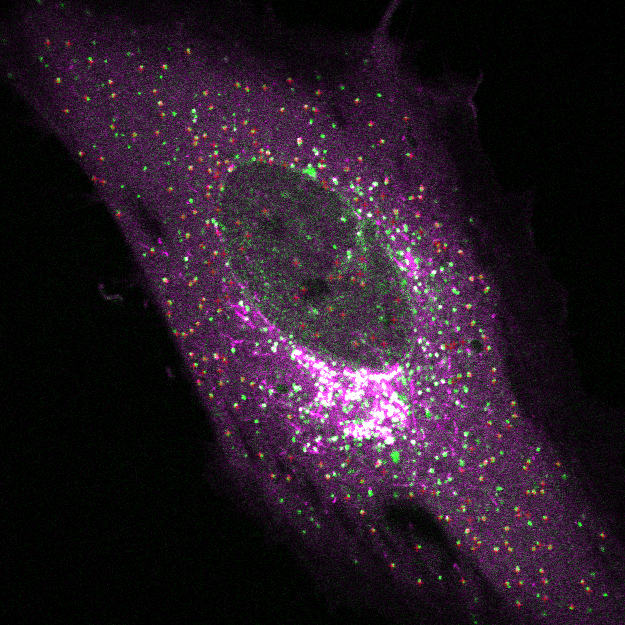

i = 3; %image
%% Import each channel image and composite creation
warning('off','all')
ImageDataStore = datastore(files{i,1},'ReadFcn',@imfinfo);
data = readall(ImageDataStore);
image_w = data{1,1}.Width;
image_h = data{1,1}.Height;
BitDepth = data{1,1}.BitDepth;
if BitDepth == 8
    channel_1 = zeros(image_h,image_w,'uint8');
    channel_2 = zeros(image_h,image_w,'uint8');
elseif BitDepth == 16
    channel_1 = zeros(image_h,image_w,'uint16');
    channel_2 = zeros(image_h,image_w,'uint16');
else
    channel_1 = zeros(image_h,image_w,'double');
    channel_2 = zeros(image_h,image_w,'double');
end
tstack  = Tiff(files{i,1},'r'); % read tiff file from pathway
channel_1(:,:)  = tstack.read(); % creates empty matrix with the image properties
channel_1 = uint8(channel_1/256);
channel_1 = imadjust(channel_1); %adjustes intensity range
tstack  = Tiff(files{i,2},'r'); % read tiff file from pathway
channel_2(:,:)  = tstack.read(); % creates empty matrix with the image properties
channel_2 = uint8(channel_2/256);
channel_2 = imadjust(channel_2); %adjustes intensity range
composite = imfuse(channel_2(:,:),channel_1(:,:),...
        'falsecolor','ColorChannels',[2 1 2],'Scaling','none');
% Centroid filtering by cutoff

imshow(composite)
hold on
logi = distances{1,i} < cutoff;
x = centroids{1,i}(logi,2) + 0.5;
y = centroids{1,i}(logi,1) + 0.5;
scatter(x,y,'+','r')

clearvars BitDepth channel_1 channel_2 composite i image_h image_w ImageDataStore logi tstack x y